# Examples for using the `planet3D` and `background` functions.

Copyright © 2021 Tamas Kis

## Example #1: Celestial bodies with the Milky Way in the background.

Initialize the figure.

figure;

Choose which planet to plot. For this example, we choose Mars.

planet = 'Mars';

Produce the plot.

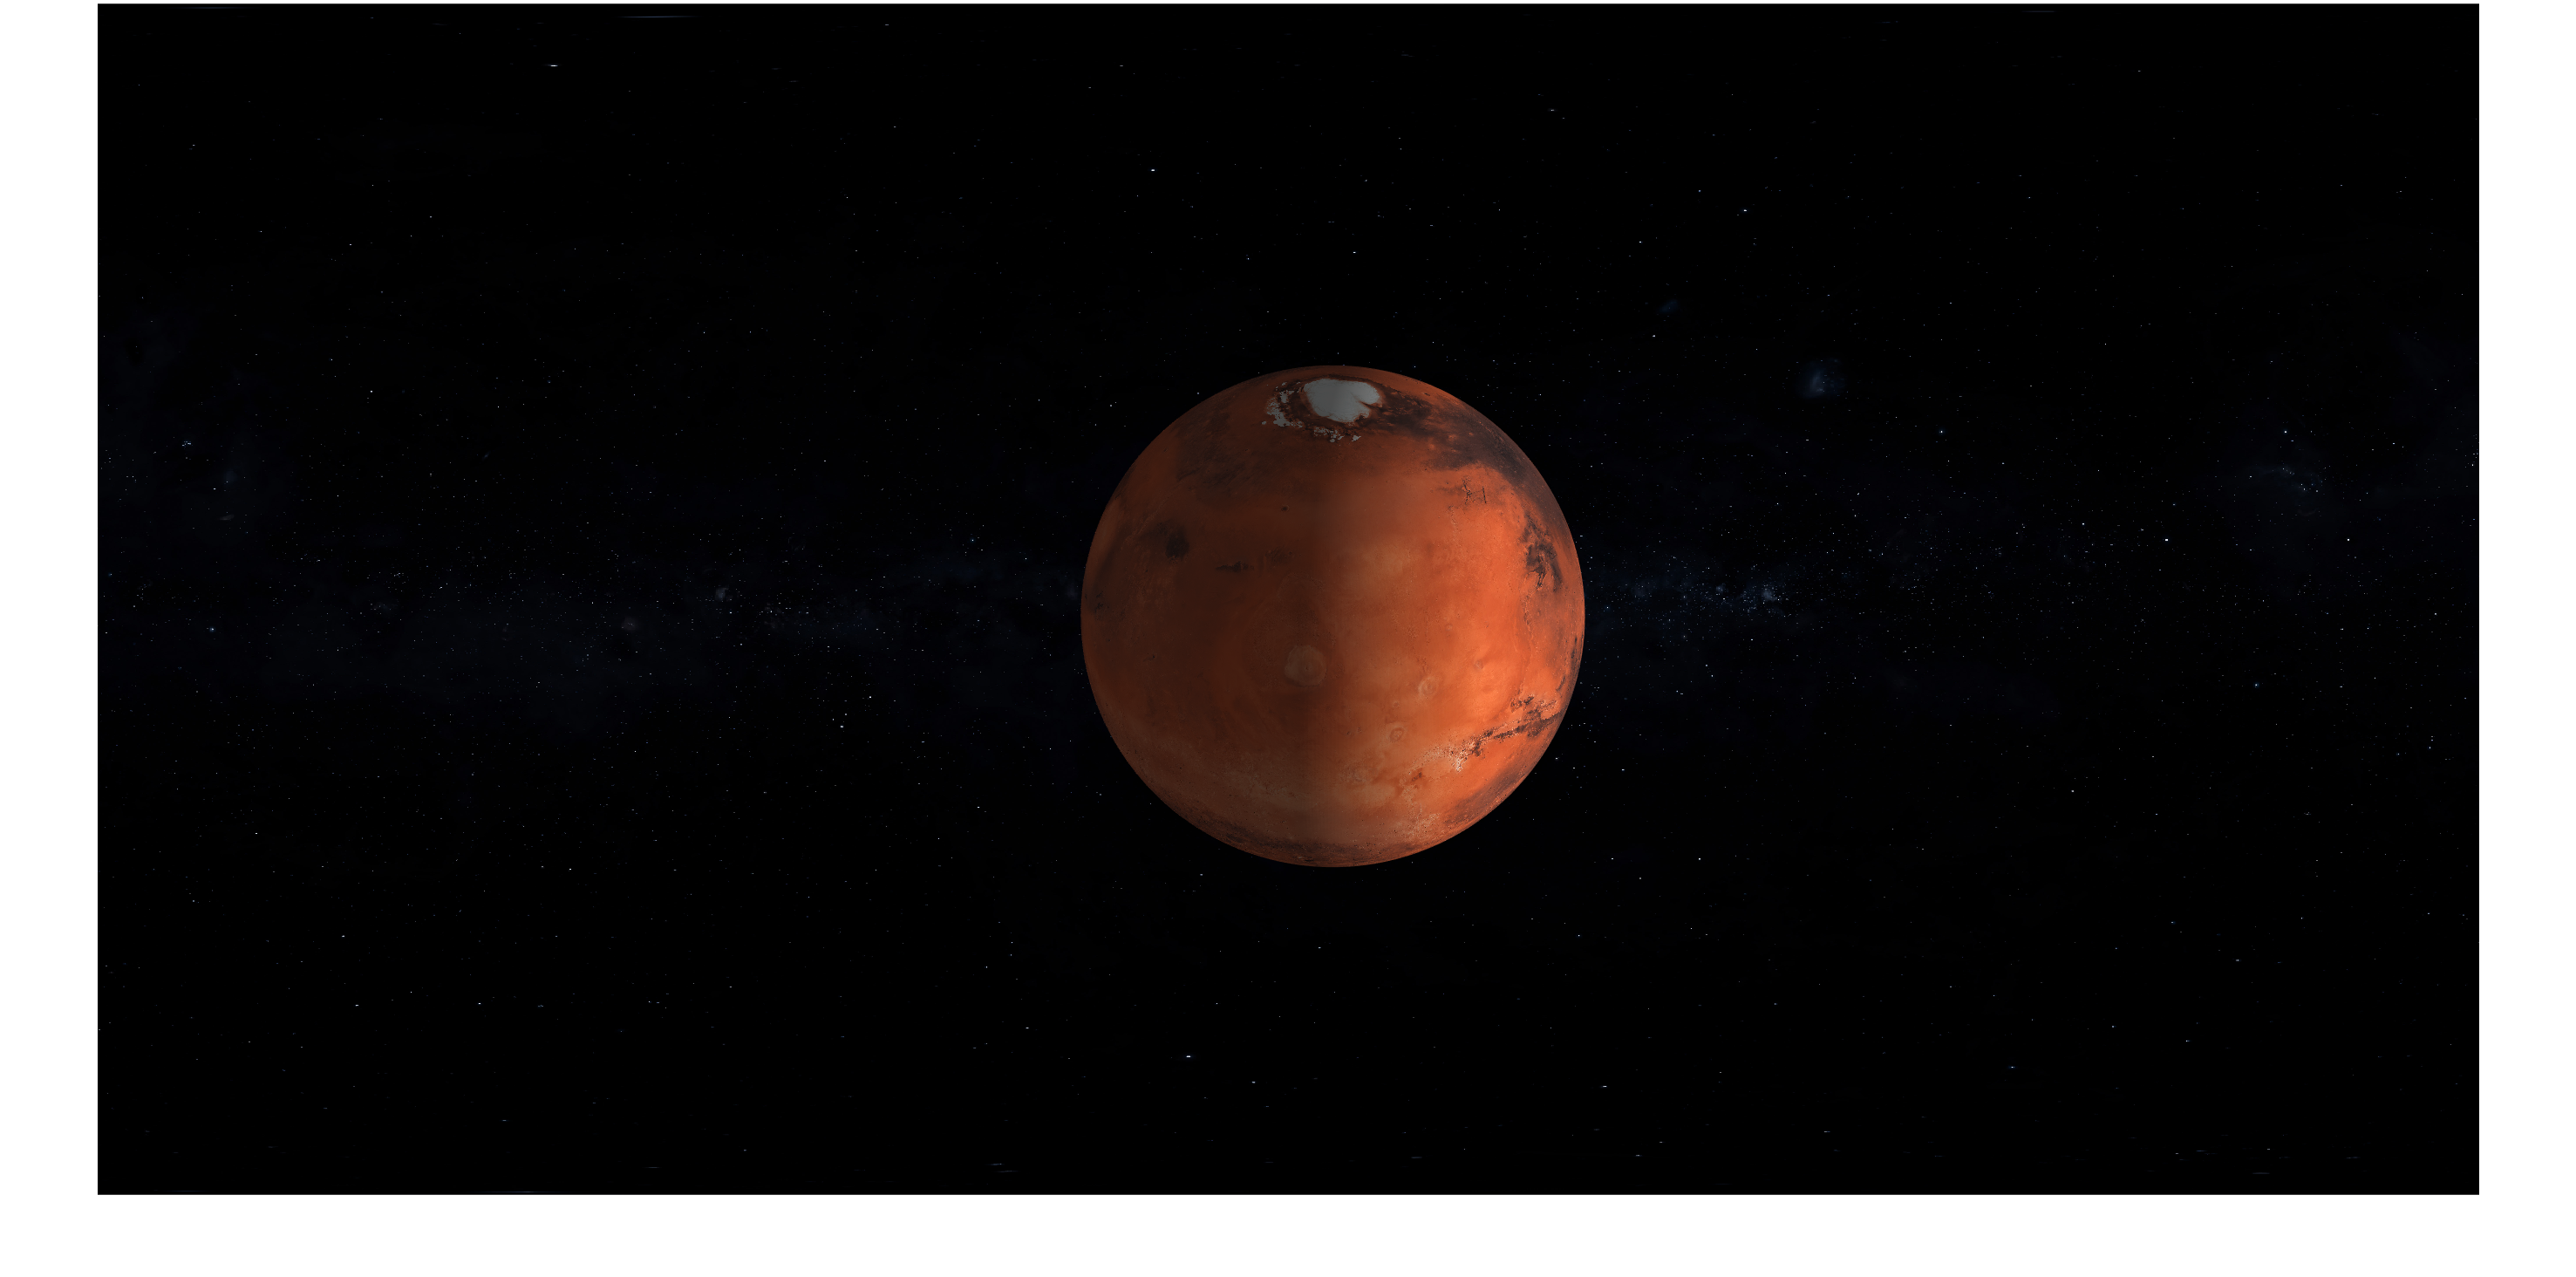

figure;
background('Milky Way');
planet3D(planet);
light('position',[1,-1,0]);

## Example #2: Plot Saturn with respect to the ecliptic plane on white background with grid lines.

Set the reference plane to the ecliptic plane.

opts_example2.reference_plane = 'ecliptic';

Create the figure.

figure;
planet3D('Saturn',opts_example2);
light('position',[1,-1,0]);
grid on;

Changes viewpoint.

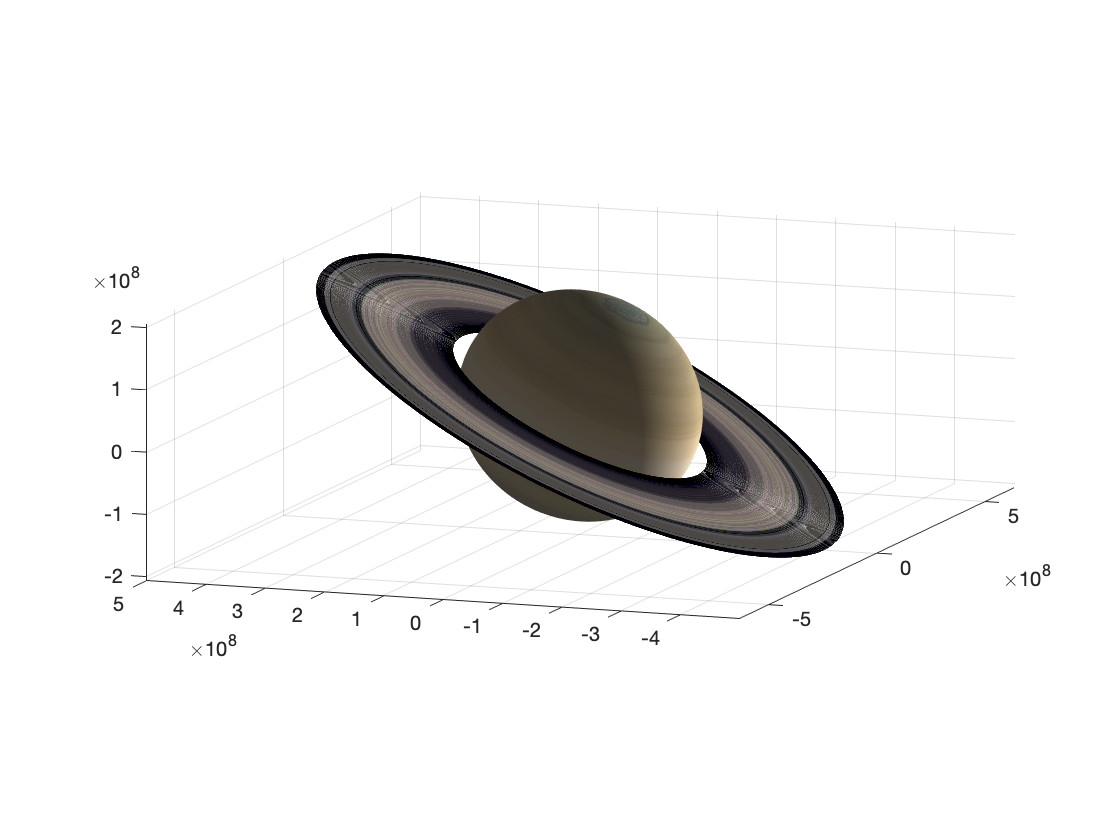

view(-70,10)

## Example #3: Plotting Earth coastlines with respect to ecliptic plane on white background with grid lines. Earth is also rotated about its third axis.

Set the reference plane to the ecliptic plane.

opts_example3.reference_plane = 'ecliptic';

Rotates Earth about its 3rd axis by 45 degrees.

opts_example3.theta = 45;

Create the figure.

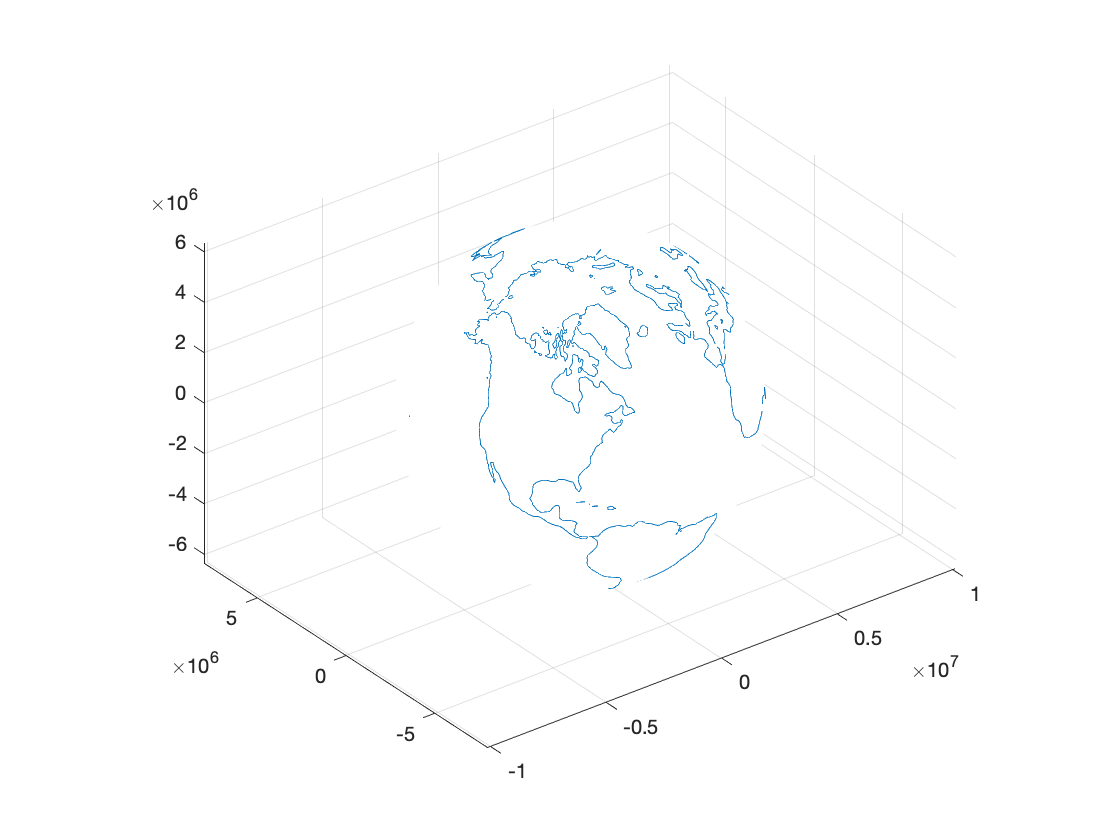

figure;
planet3D('Earth Coastlines',opts_example3);
grid on;

## Example #4: Plot elliptical trajectory around transparent Earth on black background with grid lines.

We first need to set orbit parameters.

p = 15000000;   % semi-latus rectum [m]
e = 0.5;        % eccentricity
i = 45;         % inclination [deg]
Om = 245;       % right ascension of the ascending node [deg]
w = 0;          % argument of periapsis [deg]

Next, we can determine the orbit in the perifocal plane.

% array for true anomaly [rad]
nu = 0:0.01:(2*pi);

% position components in perifocal frame [m]
rP = p*cos(nu)./(1+e*cos(nu));
rQ = p*sin(nu)./(1+e*cos(nu));
rW = zeros(size(nu));

We then rotate the position components from the perifocal frame to the Earth-centered inertial (ECI) frame.

% precomputes trigonometric functions
sO = sind(Om);
cO = cosd(Om);
si = sind(i);
ci = cosd(i);
sw = sind(w);
cw = cosd(w);

% rotation matrix
R_pqw2eci = [cO*cw-sO*ci*sw   -cO*sw-sO*ci*cw    sO*si;
             sO*cw+cO*ci*sw   -sO*sw+cO*ci*cw   -cO*si;
             si*sw             si*cw             ci];

% rotates coordinates of orbit to ECI frame
r_eci = R_pqw2eci*[rP;rQ;rW];
rI = r_eci(1,:);
rJ = r_eci(2,:);
rK = r_eci(3,:);

We initialize the figure and plot a plain black background.

figure;
background('Black');

Next, we set the transparency of Earth to 75%.

opts_example4.transparency = 0.75;

Plotting the Earth (with clouds) with 75% transparency together with the orbit,

hold on;
planet3D('Earth Cloudy',opts_example4);
plot3(rI,rJ,rK,'color',[0.5490,0.0824,0.0824],'linewidth',1.5);
hold off;

To plot a grid on the black background, we set the grid lines to white and change their transparency to 75% transparency (i.e. 25% opacity).

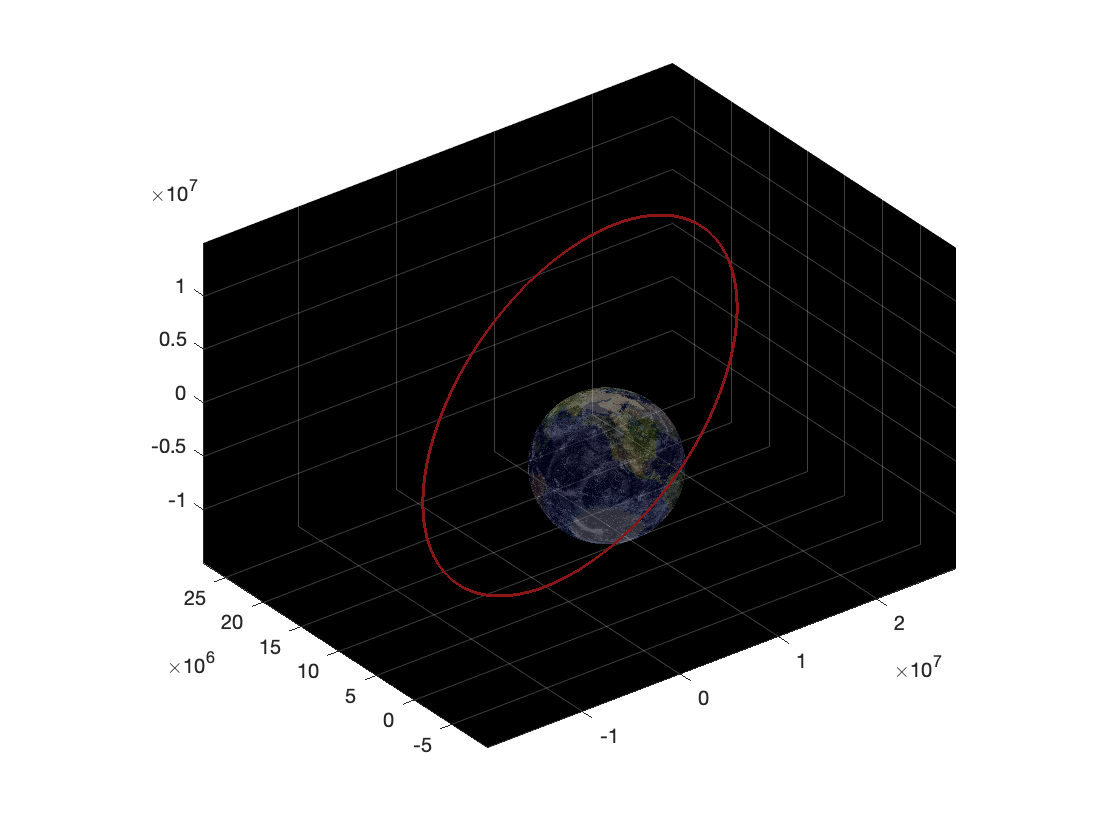

% turn grid on
grid on;

% get axis handle
ax = gca;

% set grid lines to white
ax.GridColor = [1,1,1];

% set grid lines to 75% transparency (25% opacity)
ax.GridAlpha = 0.25;